# Volumetric Efficiency

Define the volumetric efficiency $\eta_{\mathrm{vol}}$ as a third-order polynomial.

- **Goal**: Allow users to provide intuitive parameters for the volumetric efficiency, and then compute coefficients for the polynomial automatically behind the scene. Generate a Matlab function file which can do this procedure.

**NOTE: This Live Script will generate a file in the working folder. **The generated Matlab function file will be used in the Simscape source of the intake system component.

For the technical details of the volumetric efficiency, see for example:

- Lars Eriksson, Lars Nielsen, "*Modeling and Control of Engines and Drivelines*", Wiley (2014), page 76-77, "4.3.3 Volumetric Efficiency".

% User parameters
syms F_0 x_peak F_peak x_max F_xmax

% Third-order polynomial
syms  c_0  c_1  c_2  c_3  x
F = c_0 + c_1*x + c_2*x^2 + c_3*x^3

$$F = c_{3}\,x^{3}+c_{2}\,x^{2}+c_{1}\,x+c_{0}$$

dFdx = diff(F, x)

$$dFdx = 3\,c_{3}\,x^{2}+2\,c_{2}\,x+c_{1}$$

% 1. at RPM=0
expr1 = subs(F, x, 0) == F_0

$$expr1 = c_{0}=F_{0}$$

% 2. at peak, the slope is zero
expr2 = subs(dFdx, x, x_peak) == 0

$$expr2 = 3\,c_{3}\,{x_{\mathrm{peak}}}^{2}+2\,c_{2}\,x_{\mathrm{peak}}+c_{1}=0$$

% 3. at peak
expr3 = subs(F, x, x_peak) == F_peak

$$expr3 = c_{3}\,{x_{\mathrm{peak}}}^{3}+c_{2}\,{x_{\mathrm{peak}}}^{2}+c_{1}\,x_{\mathrm{peak}}+c_{0}=F_{\mathrm{peak}}$$

% 4. at max RPM
expr4 = subs(F, x, x_max) == F_xmax

$$expr4 = c_{3}\,{x_{\max}}^{3}+c_{2}\,{x_{\max}}^{2}+c_{1}\,x_{\max}+c_{0}=F_{\mathrm{xmax}}$$

sol = solve([expr1,expr2,expr3,expr4], {c_0,c_1,c_2,c_3})

sol = struct with fields:
    c_0: [1×1 sym]
    c_1: [1×1 sym]
    c_2: [1×1 sym]
    c_3: [1×1 sym]

sol.c_0

$$ans = F_{0}$$

sol.c_1

$$ans = -\frac{2\,F_{0}\,{x_{\max}}^{3}+F_{0}\,{x_{\mathrm{peak}}}^{3}-2\,F_{\mathrm{peak}}\,{x_{\max}}^{3}-F_{\mathrm{xmax}}\,{x_{\mathrm{peak}}}^{3}-3\,F_{0}\,{x_{\max}}^{2}\,x_{\mathrm{peak}}+3\,F_{\mathrm{peak}}\,{x_{\max}}^{2}\,x_{\mathrm{peak}}}{x_{\mathrm{peak}}\,\left({x_{\max}}^{3}-2\,{x_{\max}}^{2}\,x_{\mathrm{peak}}+x_{\max}\,{x_{\mathrm{peak}}}^{2}\right)}$$

sol.c_2

$$ans = \frac{F_{0}\,{x_{\max}}^{3}+2\,F_{0}\,{x_{\mathrm{peak}}}^{3}-F_{\mathrm{peak}}\,{x_{\max}}^{3}-2\,F_{\mathrm{xmax}}\,{x_{\mathrm{peak}}}^{3}-3\,F_{0}\,x_{\max}\,{x_{\mathrm{peak}}}^{2}+3\,F_{\mathrm{peak}}\,x_{\max}\,{x_{\mathrm{peak}}}^{2}}{{x_{\mathrm{peak}}}^{2}\,\left({x_{\max}}^{3}-2\,{x_{\max}}^{2}\,x_{\mathrm{peak}}+x_{\max}\,{x_{\mathrm{peak}}}^{2}\right)}$$

sol.c_3

$$ans = -\frac{F_{0}\,{x_{\max}}^{2}+F_{0}\,{x_{\mathrm{peak}}}^{2}-F_{\mathrm{peak}}\,{x_{\max}}^{2}-F_{\mathrm{xmax}}\,{x_{\mathrm{peak}}}^{2}-2\,F_{0}\,x_{\max}\,x_{\mathrm{peak}}+2\,F_{\mathrm{peak}}\,x_{\max}\,x_{\mathrm{peak}}}{{x_{\mathrm{peak}}}^{2}\,\left({x_{\max}}^{3}-2\,{x_{\max}}^{2}\,x_{\mathrm{peak}}+x_{\max}\,{x_{\mathrm{peak}}}^{2}\right)}$$

% Generate a Matlab function file.
% This is used in Simscape source.
matlabFunction( [sol.c_0, sol.c_1, sol.c_2, sol.c_3], ...
    'File','volumetricEfficiencyParams', ...
    'Vars',{F_0,x_peak,F_peak,x_max,F_xmax})

ans = function_handle with value:
    @volumetricEfficiencyParams

## Check

The following corresponds to the code in Simscape source.

% User parameters
eta_v_0 = 0.7;
rpm_eta_peak = 4000;
eta_v_peak = 0.9;
rpm_max = 7000;
eta_v_rpm_max = 0.6;

% Automatically compute the coefficients
k = volumetricEfficiencyParams( eta_v_0, ...
      rpm_eta_peak/60*(2*pi), ...
      eta_v_peak, ...
      rpm_max/60*(2*pi), ...
      eta_v_rpm_max)

k =     0.7000    0.0005    0.0000   -0.0000


Visually check

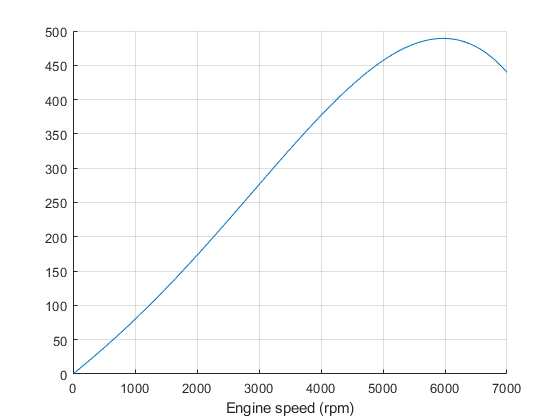

rpm = linspace(0, rpm_max, 100);

x = rpm/60*(2*pi);  % x in rad/s
eta_vol = k(1) + k(2)*x + k(3)*x.^2 + k(4)*x.^3;
mdotlike = eta_vol.*x;

figure;  hold on
%plot(rpm, eta_vol)
plot(rpm, mdotlike)
grid on
xlabel('Engine speed (rpm)')

%ylabel('Volumetric efficiency')